### Модальное управление

Зададим систему линейных уравнений ДПТ

J = 0.01;   % Момент инерции ротора kg.m^2
b = 0.1;    % Коэффициент затухания мех. системы Nms
K = .01;    % ЭДС константа Nm/A
R = 1.0;    % Сопротивление Ohms
L = 0.5;    % Индуктивность Henrys
A = [-b/J K/J; -K/L -R/L];
B = [0; 1/L];
C = [1 1];
D = 0;
W = ss(A,B,C,D);

Оценим критерий устойчивости

pole(W) % найдем полюса системы

ans =    -9.9975
   -2.0025


Все полюса отрицательны, значит система устойчива

Оценим управляемость системы

rank(ctrb(A,B)) % если ранг равен порядку системы то она полностью управляема

ans = 2

Система полностью управляема

Найдем реакцию системы на ступенчатый сигнал

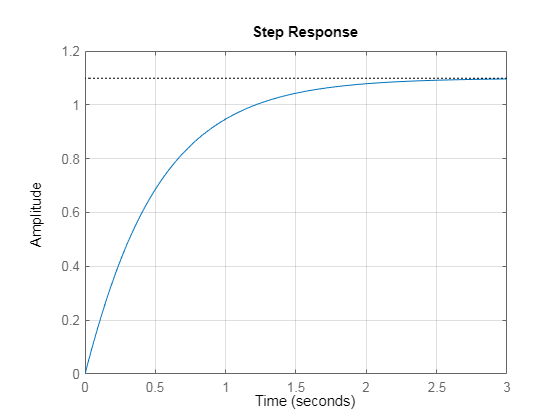

step(W)
grid on

Подставим полюса в замкнутую систему

p = 4.45*[-1 -1.1]; % заданные полюса
K = place(A,B,p) % матрица К

K =    14.1564   -1.3275


Проверим полюса замкнутой системы

AClosed = A - B*K;
BClosed = B;
CClosed = C;
DClosed = D;
Wclosed = ss(AClosed,BClosed,CClosed,DClosed);
pole(Wclosed)

ans =    -4.8950
   -4.4500


Полюса совпадают с задаными

Найдем реакцию замкнутой системы на ступенчатый сигнал

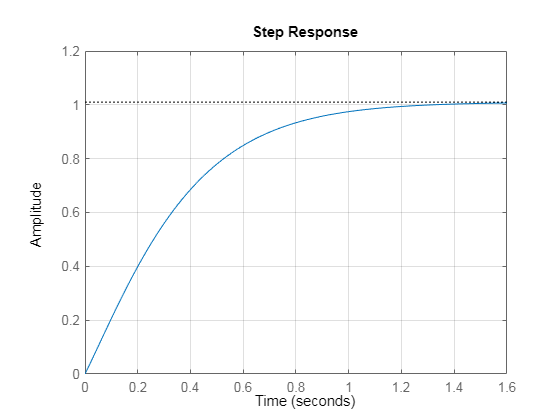

step(Wclosed)
grid on

#### Найдем матрицу К по алгоритму

Запишем матрицу замкнутой системы

L = length(B);
k = sym('k',[1,L]);
F = A - B*k % найдем матрицу F

$$F = \left(\begin{array}{cc} -10 & 1\\ -2\,k_{1}-\frac{1}{50} & -2\,k_{2}-2 \end{array}\right)$$

Найдем характеристический полином

syms lamda
polyF = det(lamda*eye(L)-F) % характеристический полином

$$polyF = 2\,k_{1}+20\,k_{2}+12\,\mathrm{lamda}+2\,k_{2}\,\mathrm{lamda}+{\mathrm{lamda}}^{2}+\frac{1001}{50}$$

CoefF = fliplr(coeffs(polyF,lamda)) % коэффициенты полинома

$$CoefF = \left(\begin{array}{ccc} 1 & 2\,k_{2}+12 & 2\,k_{1}+20\,k_{2}+\frac{1001}{50} \end{array}\right)$$

CoefF(1) = [];

Назначим желаемый характеристический полином

polyL = (lamda-p(1))*(lamda-p(2)) % желаемый полином

$$polyL = \left(\mathrm{lamda}+\frac{89}{20}\right)\,\left(\mathrm{lamda}+\frac{979}{200}\right)$$

CoefL = fliplr(coeffs(polyL,lamda)) % коэффициенты полинома

$$CoefL = \left(\begin{array}{ccc} 1 & \frac{1869}{200} & \frac{87131}{4000} \end{array}\right)$$

CoefL(1) = [];

Найдем элементы матрицы К

K = solve(CoefF == CoefL);
K = double([K.k1 K.k2]) % матрица К

K =    14.1564   -1.3275
